## Aerospace Control Systems - Quadrotor Control Systems Design - 2021/2022 

## Students: Mustafa Orhan - 10834906 ---- Onur Kadıoğlu - 10818335 ---- Kuzey Koçal - 10820058

## Professor: Marco Lovera

clear
close all
clc

Y_v_nom = -0.1068;       % [1/s]         -> 4.26 %
Y_p_nom = 0;             % [m/(s rad)]   -> 2.03 %
L_v_nom = 0;             % [rad s/m]     -> 1.83 %
L_p_nom = -2.6478;       % [1/s]         -> 2.01 %

Y_d_nom = 0;             % [m/s^2]       -> 1.37 %
L_d_nom = 450.7085;      % [rad/s^2]      -> 0.81 %

Uncertainties are given in terms of standard deviations $\sigma$ (provided as percentage of corresponding nominal values) assuming a Gaussian density for each parameter.

Since we have to ensure robustness of stability to model uncertainty associated with $\pm 3 \sigma$ ranges on all parameters we define the following percentage uncertainties and use it in [`ureal`](https://it.mathworks.com/help/robust/ref/ureal.html).

unc_Y_v = 3*4.26;
unc_L_p = 3*2.01;
unc_L_d = 3*0.81;

% Stability Derivatives
Y_v = ureal('Y_v',Y_v_nom,'Perc',unc_Y_v);
Y_p = Y_p_nom;
L_v = L_v_nom;
L_p = ureal('L_p',L_p_nom,'Perc',unc_L_p);

% Control Derivatives
Y_d = Y_d_nom;
L_d = ureal('L_d',L_d_nom,'Perc',unc_L_d);

Our plant has one input, *i.e.*, the rolling moment that ranges between [-100 100], and two outputs the roll angle $\phi$ and the roll rate $p$. For both the nominal and uncertain plants the input and output must be specified.

g = 9.81;

% State Space Model
A = [Y_v Y_p g; L_v L_p 0; 0 1 0];
B = [Y_d L_d 0]';
C = [0 1 0; 0 0 1];
D = [0 0]';

Our plant has one input, *i.e.*, the lateral command $\delta_{lat}
$ that ranges between [0 100], and two outputs the roll angle $\phi$ and the roll rate $p$. For both the nominal and uncertain plants the input and output must be specified.

% Uncertain Plant
sys_ld = ss(A,B,C,D)

sys_ld =

  Uncertain continuous-time state-space model with 2 outputs, 1 inputs, 3 states.
  The model uncertainty consists of the following blocks:
    L_d: Uncertain real, nominal = 451, variability = [-2.43,2.43]%, 1 occurrences
    L_p: Uncertain real, nominal = -2.65, variability = [-6.03,6.03]%, 1 occurrences
    Y_v: Uncertain real, nominal = -0.107, variability = [-12.8,12.8]%, 1 occurrences

Type "sys_ld.NominalValue" to see the nominal value, "get(sys_ld)" to see all properties, and "sys_ld.Uncertainty" to interact with the uncertain elements.



sys_ld.u = '\delta_{lat}';
sys_ld.y = {'p','\phi'};
sys_ld_d = c2d(tf(sys_ld),0.01,'tastin');
 
% Nominal Plant
sys_ld_nom = sys_ld.NominalValue

sys_ld_nom =
 
  A = 
            x1
   x1  -0.1068
   x2        0
   x3        0
 
            x2
   x1        0
   x2   -2.648
   x3        1
 
            x3
   x1     9.81
   x2        0
   x3        0
 
  B = 
       \delta_{lat}
   x1             0
   x2         450.7
   x3             0
 
  C = 
         x1  x2
   p      0   1
   \phi   0   0
 
         x3
   p      0
   \phi   1
 
  D = 
         \delta_{lat}
   p                0
   \phi             0
 
Continuous-time state-space model.



sys_ld_nom.u = '\delta_{lat}';
sys_ld_nom.y = {'p','\phi'};

sys_ld_nom_d = c2d(tf(sys_ld_nom),0.01,'tastin');

After looking at the open loop characteristics of the given system, they may give an ideain what range we need to design the controllers for the given system.

G_delta_lat_p_nom = tf(sys_ld_nom(1))

G_delta_lat_p_nom =
 
  From input "\delta_{lat}" to output "p":
    450.7
  ---------
  s + 2.648
 
Continuous-time transfer function.



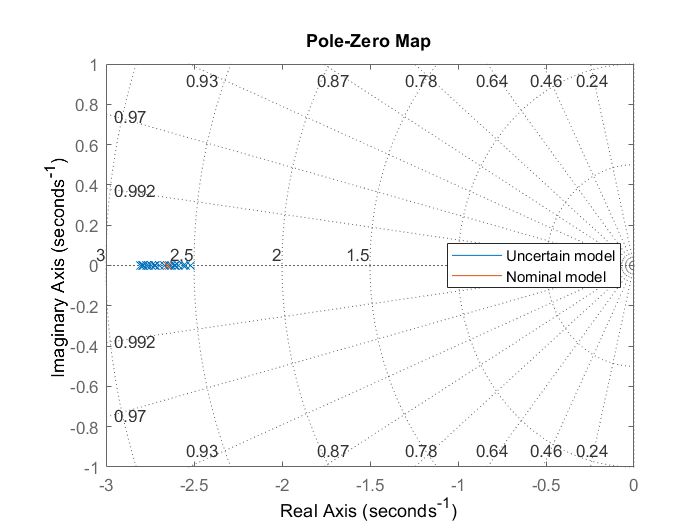


figure
pzplot(sys_ld(1));
hold on 
pzplot(sys_ld_nom(1));
grid on                               
legend('Uncertain model','Nominal model','location','east')


z_delta_lat_p = tzero(sys_ld_nom(1))

z_delta_lat_p =          0
   -0.1068


p_delta_lat_p = pole(sys_ld_nom(1))

p_delta_lat_p =    -2.6478
   -0.1068
         0


G_delta_lat_phi_nom = tf(sys_ld_nom(2))

G_delta_lat_phi_nom =
 
  From input "\delta_{lat}" to output "\phi":
      450.7
  -------------
  s^2 + 2.648 s
 
Continuous-time transfer function.



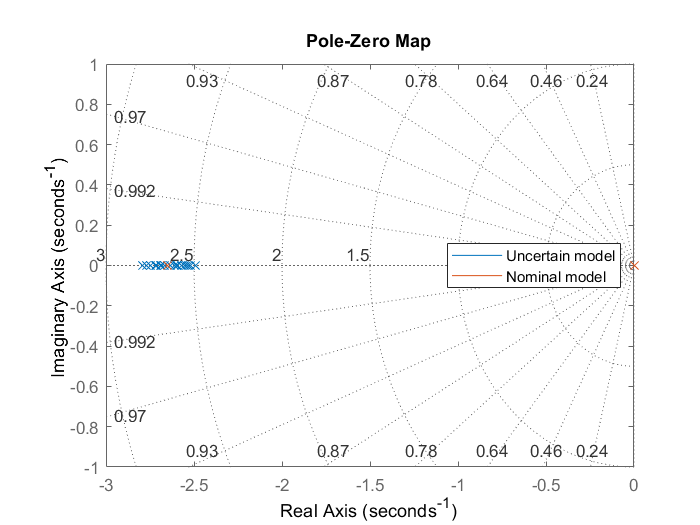


figure
pzplot(sys_ld(2));
hold on 
pzplot(sys_ld_nom(2));
grid on 
legend('Uncertain model','Nominal model','location','east')


z_delta_lat_phi = tzero(sys_ld_nom(2))

z_delta_lat_phi = -0.1068

p_delta_lat_phi = pole(sys_ld_nom(2))

p_delta_lat_phi =          0
   -2.6478
   -0.1068


One may see below the Bode plots of both outputs, and the step reponse of the nominal system and uncertain systems.

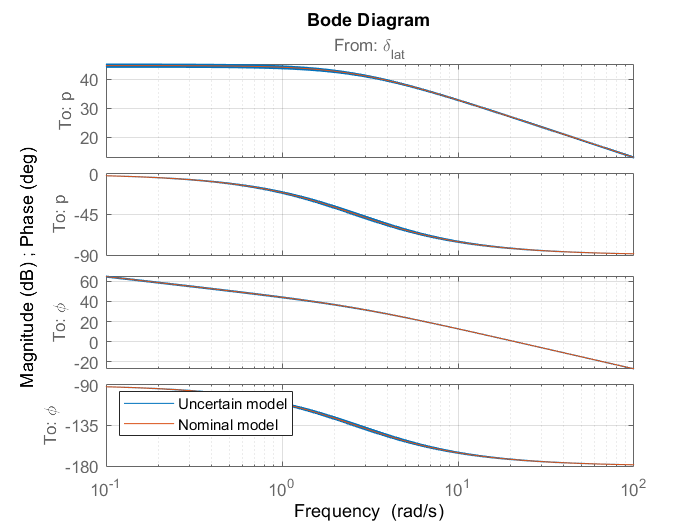

figure 
bode(sys_ld)
hold on
bode(sys_ld_nom)
grid on
legend('Uncertain model','Nominal model','location','northwest')

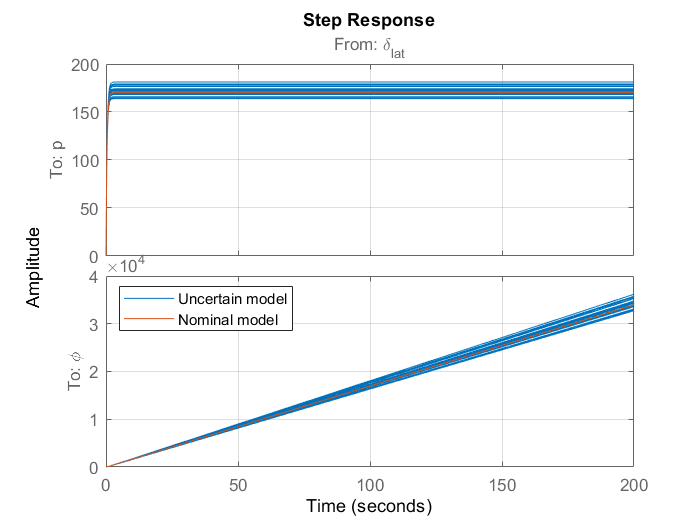


figure 
step(sys_ld)
hold on
step(sys_ld_nom)
grid on
legend('Uncertain model','Nominal model','location','northwest')

Tunable proportionial, and second order PID controller gains are defined below, afterwards, mixed sensitivity synthesis will be used for optimization.

R_phi = tunablePID('R_phi','P', 0.01)

R_phi =   Tunable discrete-time PID controller "R_phi" with formula:

 
  Kp
 

  and tunable parameters Kp.

Type "pid(R_phi)" to see the current value and "get(R_phi)" to see all properties.


R_phi.u = 'e_\phi';
R_phi.y = 'p_0';

R_p = tunablePID2('R_p','PID', 0.01)

R_p =   Tunable discrete-time 2-DOF PID controller "R_p" with equation:

                        Ts                   1     
  u = Kp (b*r-y) + Ki ------ (r-y) + Kd ----------- (c*r-y)
                        z-1             Tf+Ts/(z-1)

  where r,y are the controller inputs and Kp, Ki, Kd, Tf, b, c are tunable gains.

Type "pid2(R_p)" to see the current value and "get(R_p)" to see all properties.


R_p.c.Value = 0;
R_p.c.Free = false;
R_p.b.Value = 1;
R_p.b.Free = false;
R_p.Tf.Value = 0.01;
R_p.Tf.Free = false;
R_p.u = {'p_0','p'};
R_p.y = {'\delta_{lat}'};

SumOuter = sumblk('e_\phi = \phi_0 - \phi');

%CL_tun = connect(SumOuter,R_phi,R_p,sys_ld_nom,'\phi_0',{'\phi','p'})

CL_tun_d = connect(SumOuter,R_phi,R_p,sys_ld_nom_d,'\phi_0',{'\phi','p'})

CL_tun_d =

  Generalized discrete-time state-space model with 2 outputs, 1 inputs, 4 states, and the following blocks:
    R_p: Tunable 2-DOF PID controller, 1 occurrences.
    R_phi: Tunable PID controller, 1 occurrences.

Type "ss(CL_tun_d)" to see the current value, "get(CL_tun_d)" to see all properties, and "CL_tun_d.Blocks" to interact with the blocks.



The given performance requirements are implemented below, the sensitivity, and complementary sensitivity functions are taken from the system, and shown. 

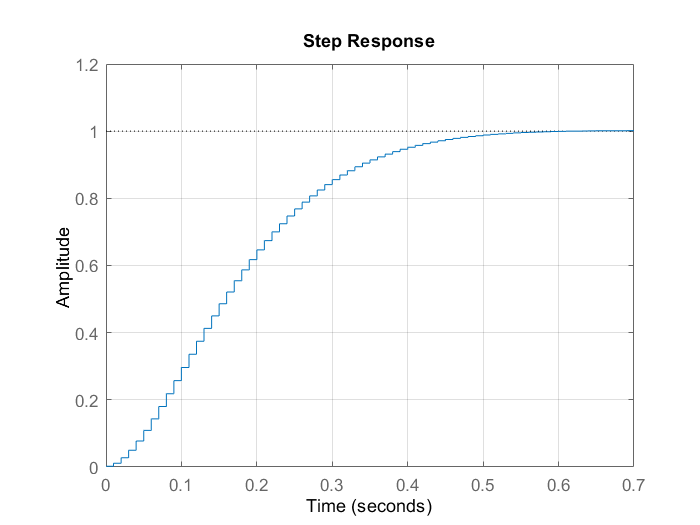

omega_n = 10;       % [rad/s]
xi = 0.9;

s = tf('s');

F_2 = omega_n^2/(s^2 + 2*s*xi*omega_n + omega_n^2);
F_2_d = c2d(F_2, 0.01,'tastin');
S_2 = 1-F_2;
S_2_d = c2d(S_2, 0.01,'tastin');

figure
step(F_2_d)
grid on


stepinfo(F_2_d)

ans = struct with fields:
        RiseTime: 0.2900
    SettlingTime: 0.4700
     SettlingMin: 0.9047
     SettlingMax: 1.0015
       Overshoot: 0.1537
      Undershoot: 0
            Peak: 1.0015
        PeakTime: 0.7100


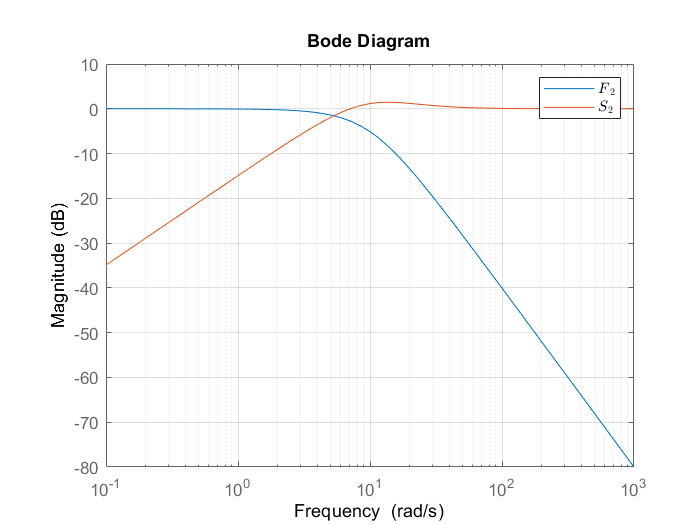

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
legend('$F\_2$','$S\_2$','interpreter','latex')


$$W_p(s) = \frac{\frac{s}{M} + \omega_b}{s + A \omega_b}$$


The objective is that $1/W_p(s)$ is used to shape our sensitivity function in order to have $S(s) \simeq S_2(s)$.

Where $M$ is related to the peak, $A$ is related to the value at steady state and $\omega_b$ is related to the cross-over frequency and so to the settling time of our response.

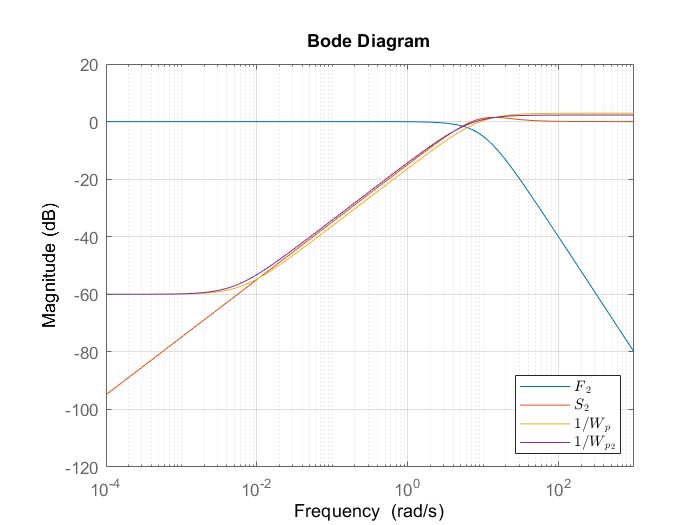

M = 1.4;
A = 1e-3;
omega_b = 0.65*omega_n;

W_p = (s/M + omega_b)/(s + A*omega_b);
W_p2inv = makeweight(1e-3,8,1.3,0,1);
W_p2 = 1/W_p2inv;
W_p_d = c2d(W_p, 0.01,'tastin');
W_p2inv_d = c2d(W_p2inv, 0.01,'tastin');
W_p2_d = c2d(W_p2, 0.01,'tastin');

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
bodemag(1/W_p)
bodemag(1/W_p2)
legend('$F\_2$','$S\_2$','$1/W\_p$','$1/W\_{p\_{2}}$','interpreter','latex', 'location','southeast')

The control performance requirements are impelented below, and a control weight is defined according to below 


$$W_q(s) = \alpha \frac{s + \omega_{act} 10^{-3}}{s +  \omega_{act}}$$


where $\omega_{act}$ is related to the frequency of the actuators, while $\alpha$ represent the high frequency gain of the weight $W_q(s)$ and shall be large enough so as to limit the magnitude of $Q(s)$ beyond the bandwidth. The weight will be used in $H_\infty$ synthesis.

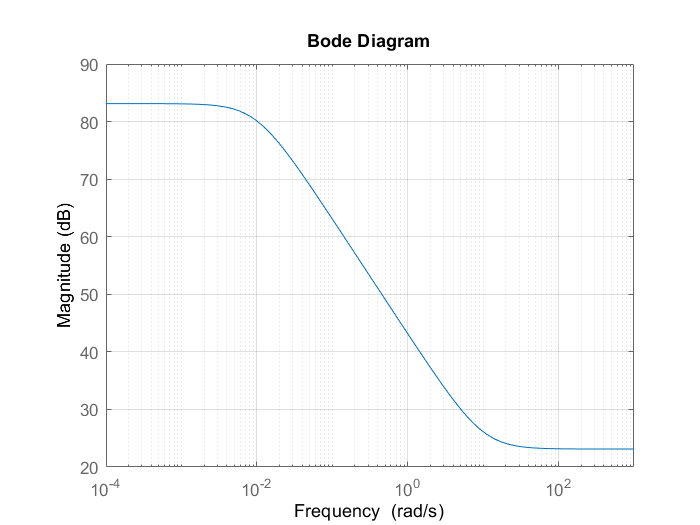

alpha = deg2rad(20)/5;
w_tau = 10;

W_q = alpha*(s+w_tau*1e-3)/(s+w_tau);

figure
bodemag(1/W_q)
grid on

One may  use [`hinfstruct`](https://it.mathworks.com/help/robust/ref/lti.hinfstruct.html) to tune the controllers. Through this function one may  tune the free parameters of the closed loop model to minimize its $H_\infty$ norm.

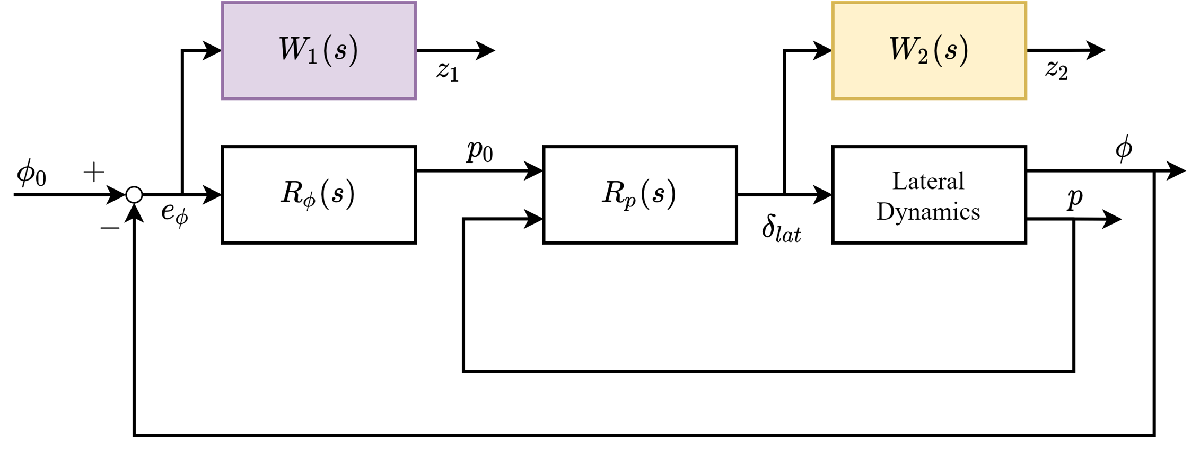

Where $W_1(s) = W_p(s)$ and $W_2(s) = W_q(s)$.

First of all we have to define input and output of our weighting functions.

W_p.u = 'e_\phi';
W_p.y = 'z_1';

W_q.u = '\delta_{lat}';
W_q.y = 'z_2';

W_p_d = c2d(W_p, 0.01, 'tastin');
W_q_d = c2d(W_q, 0.01, 'tastin');

CL0 = connect(R_p, R_phi, sys_ld_nom_d, SumOuter, W_p_d, W_q_d,...
    '\phi_0',{'z_1','z_2'},{'\delta_{lat}','e_\phi','\phi'});

opt = hinfstructOptions('Display','final','RandomStart',10);

[CL,gamma,info] = hinfstruct(CL0,opt);

Final: Peak gain = 0.753, Iterations = 82
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.753, Iterations = 49
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.753, Iterations = 42
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.753, Iterations = 54
Final: Peak gain = 0.753, Iterations = 35
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.753, Iterations = 32
Final: Peak gain = 0.753, Iterations = 42
Final: Peak gain = 0.753, Iterations = 57
Final: Peak gain = 0.753, Iterations = 65
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.753, Iterations = 35
Final: Peak gain = 0.753, Iterations = 60


showTunable(CL)

R_p =
 
                        Ts                   1     
  u = Kp (b*r-y) + Ki ------ (r-y) + Kd ----------- (c*r-y)
                        z-1             Tf+Ts/(z-1)

  with Kp = 0.399, Ki = 1.05, Kd = -4.38e-08, Tf = 0.01, b = 1, c = 0, Ts = 0.01
 
Name: R_p
Sample time: 0.01 seconds
Discrete-time 2-DOF PIDF controller in parallel form.
-----------------------------------
R_phi =
 
  Kp = 8.64
 
Name: R_phi
P-only controller.


F_phi = getIOTransfer(CL,'\phi_0','\phi');
ss(F_phi)

ans =
 
  A = 
                       ?
   ?             0.06431
   ?             -0.1137
   ?                   0
   R_p.Integ     -0.0114
   R_p.Deriv       1.184
 
                       ?
   ?             -0.6325
   ?               1.895
   ?                   1
   R_p.Integ   -0.007927
   R_p.Deriv     -0.7034
 
                       ?
   ?           -0.004159
   ?             -0.9744
   ?                   0
   R_p.Integ  -5.213e-05
   R_p.Deriv   -0.004625
 
               R_p.Integ
   ?               1.094
   ?              0.1368
   ?                   0
   R_p.Integ      0.9873
   R_p.Deriv       1.217
 
               R_p.Deriv
   ?          -4.546e-06
   ?          -5.683e-07
   ?                   0
   R_p.Integ   5.274e-08
   R_p.Deriv  -5.056e-06
 
  B = 
               \phi_0
   ?            3.578
   ?           0.4473
   ?                0
   R_p.Integ  0.04484
   R_p.Deriv    3.979
 
  C = 
                  ?
   \phi   -0.005057
 
                  ?
   \phi      0.

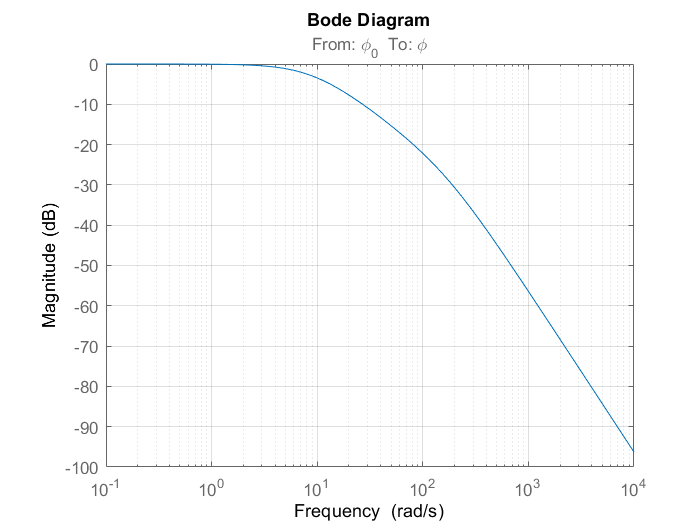


F_phi_c = d2c(tf(F_phi),'tustin');

%D_phi = [0];
%[ b , a ] = ss2tf( F_phi.A , F_phi.B, F_phi.C,D_phi );

F_phi_tf= tf(F_phi_c);

save('F_phi_tf','F_phi_tf')    %Save the transfer function into a ".mat" file to use it in the next task
figure
bodemag(F_phi_c)
grid on

One may plot the step response below and compare it to the desired one.

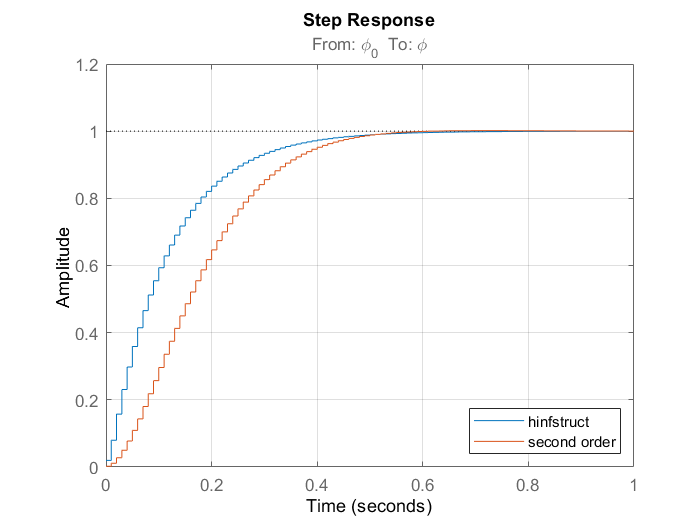

figure
step(F_phi)
hold on
step(F_2_d)
grid on
legend('hinfstruct','second order', 'location','southeast')


stepinfo(F_phi)

ans = struct with fields:
        RiseTime: 0.2400
    SettlingTime: 0.4400
     SettlingMin: 0.9053
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 1.2900


The sensitivity and its weight can be plotted to verify nominal performance.

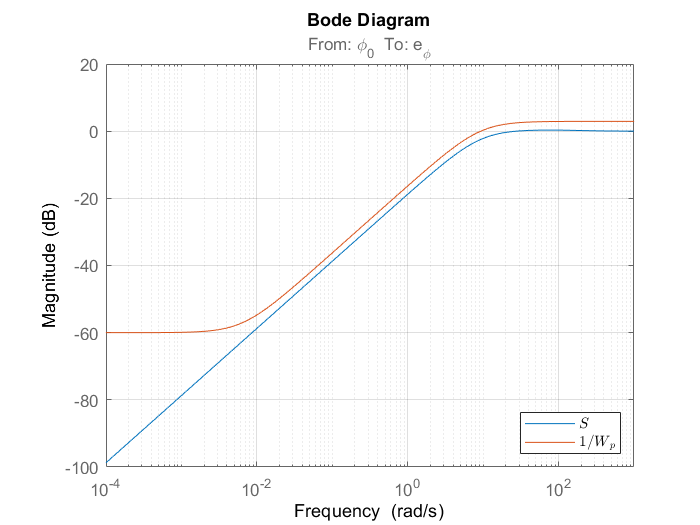

S = getIOTransfer(CL,'\phi_0','e_\phi');

S_c = d2c(tf(S), 'tastin');

figure
bodemag(S_c)
grid on
hold on
bodemag(1/W_p)
legend('$S$','$1/W\_p$','interpreter','latex', 'location','southeast')

The same can be done for the control sensitivity.

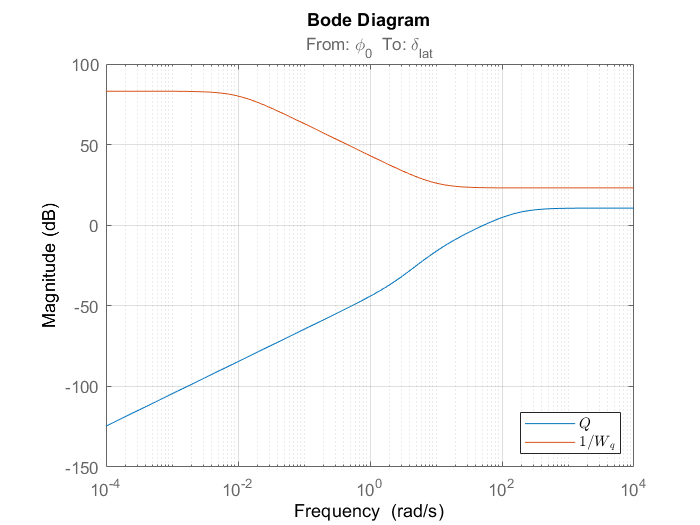

Q = getIOTransfer(CL,'\phi_0','\delta_{lat}');

Q_c = d2c(tf(Q), 'tastin');

figure
bodemag(Q_c)
grid on
hold on
bodemag(1/W_q)
legend('$Q$','$1/W\_q$','interpreter','latex', 'location','southeast')

Moreover one may verify control effort limitation.

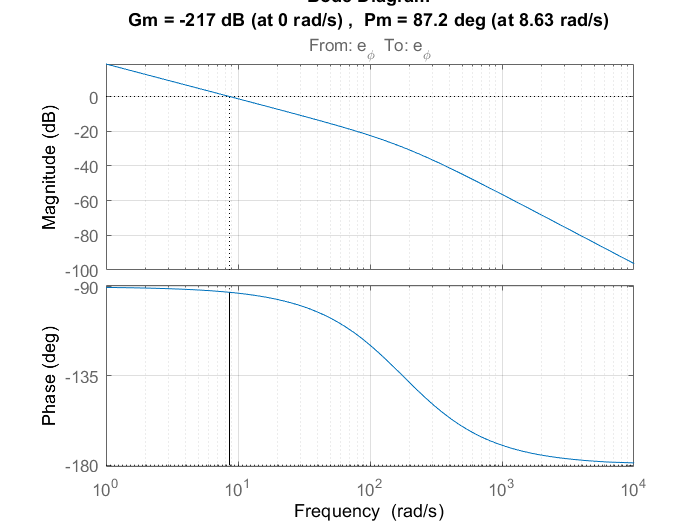

L = (1-S_c)/S_c;

figure
margin(L)
grid on

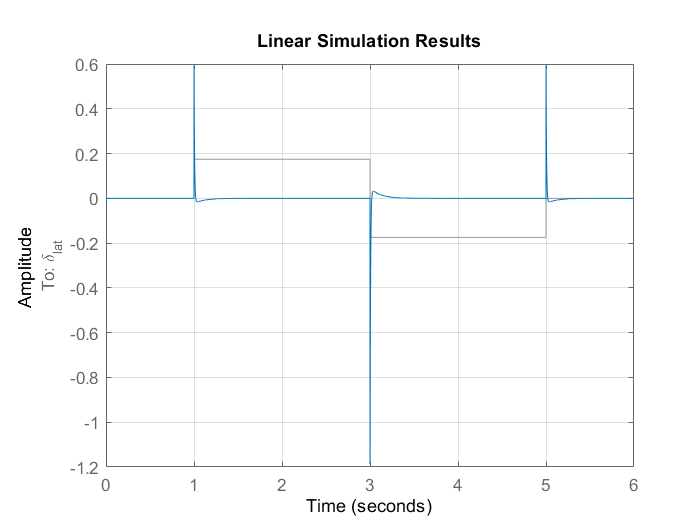

t = linspace(0,6,10^4);
u = 0*(t<=1) + 10*(t>1 & t<= 3) - 10*(t>3 & t<= 5) + 0*(t>5);
u = deg2rad(u);

figure
lsim(Q_c,u,t);

hold on
grid on

Robust stability with parametric uncertainty procedure may be seen in the subsequent part of the code;

sys_ld_array = usample(sys_ld(2),60);

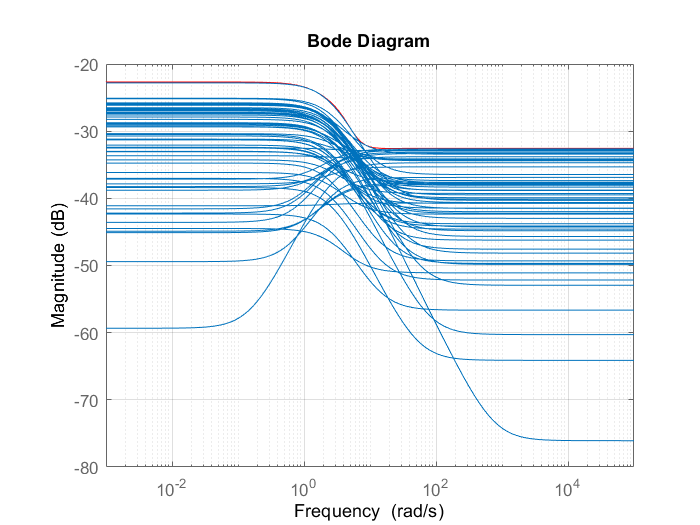

[~,Info] = ucover(sys_ld_array,sys_ld_nom(2),3);

W = Info.W1;

figure
bodemag(W,'r')
hold on
bodemag((sys_ld_nom(2)-sys_ld_array)/sys_ld_nom(2),{10e-4,10e4})
grid on

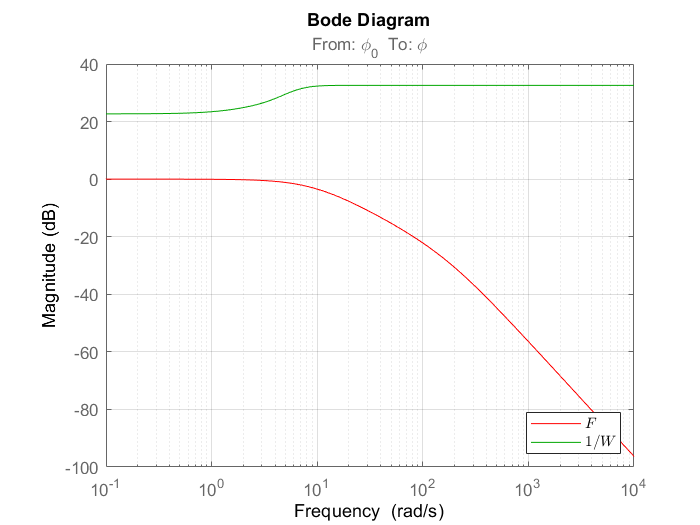

figure
bodemag(F_phi_c,'r',1/W,'g')
grid on
legend('$F$','$1/W$','interpreter','latex', 'location','southeast')

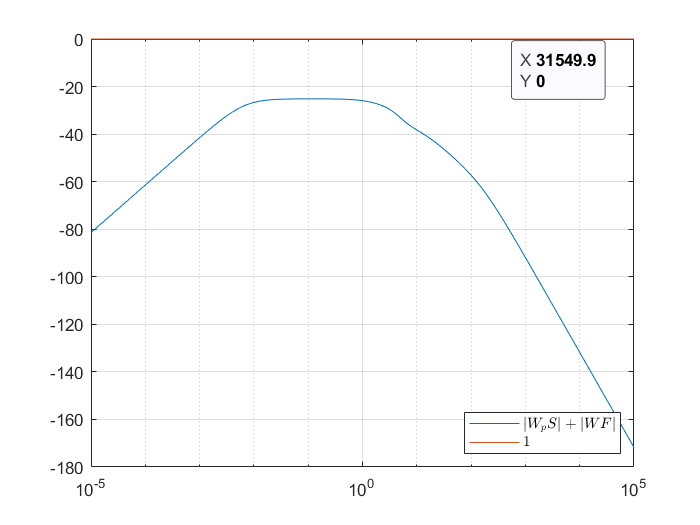

w = logspace(-5,5,500);

FW = bode(F_phi_c*W,w); 
SW = bode(S_c*W_p,w);

figure
semilogx(w, 20*log10(squeeze(FW)) + 20*log10(squeeze(SW)))
hold on 
semilogx(w,20*log10(w./w))
grid on
legend('$|W_p S|+|W F|$','$1$','interpreter','latex', 'location','southeast')  